Dato il sistema:


$$G\left(s\right)=\frac{1}{{s\left(s+3\ldotp 8\right)}^3 }$$


Progettare un controllore dinamico tale da garantire:

- Errore alla rampa unitaria inferiore inferiore del 5%

- Sovra-elongazione percentuale massima pari al 20%

- Tempo di salita minore di 2 sec

clc
clear 
close all

So dal teorema del valor finale che se il $\lim_{t\to +\infty } e\left(t\right)$ esiste allora $\lim_{t\to +\infty } e\left(t\right)=\lim_{s\to 0} \;s\cdot E\left(s\right)$ con $E\left(s\right)$ la trasformata di laplace di $e\left(t\right)$.

$E\left(s\right)=\frac{1}{1+L\left(s\right)}R\left(s\right)$ dove $R\left(s\right)$ è la trasformata del forzamento mentre $L\left(s\right)$ è la funzione di anello $C\left(s\right)\cdot G\left(s\right)$.

Sotto l'ipotesi circa la struttura di $C\left(s\right)$ precedentemente fatta e considerando che la traformata della rampa di pendenza unitaria è pari a $\frac{1}{s^2 }$ allora ciò che devo risolvere per definire il K è la seguente disequazione:


$$\lim_{s\to 0} \;s\cdot \;\frac{1}{K\cdot G\left(s\right)}\cdot \frac{1}{s^2 }<\frac{1}{20}\;=\lim_{s\to 0} \;s\frac{1}{K*\frac{1}{s{\left(s+3\ldotp 8\right)}^3 }\;}*\frac{1}{s^2 }\;\;\;\;\Longrightarrow \;\;\;\;\;\frac{1}{K*\frac{1}{54,87}}<0\ldotp 05\;\;\;\;\;\;\;\;\;\Longrightarrow \;\;\;\;\;K>1097,4$$


clc
clear 
close all

s=tf('s');

Gs = (1)/(s*(s+3.8)^3);
K=1120.45;
Cs=K;
Ls = Cs*Gs

Ls =
 
                  1120
  ------------------------------------
  s^4 + 11.4 s^3 + 43.32 s^2 + 54.87 s
 
Continuous-time transfer function.



[y,t]=step((1/s)*feedback(Ls,1));
Ws=feedback(Ls,1)

Ws =
 
                     1120
  -------------------------------------------
  s^4 + 11.4 s^3 + 43.32 s^2 + 54.87 s + 1120
 
Continuous-time transfer function.



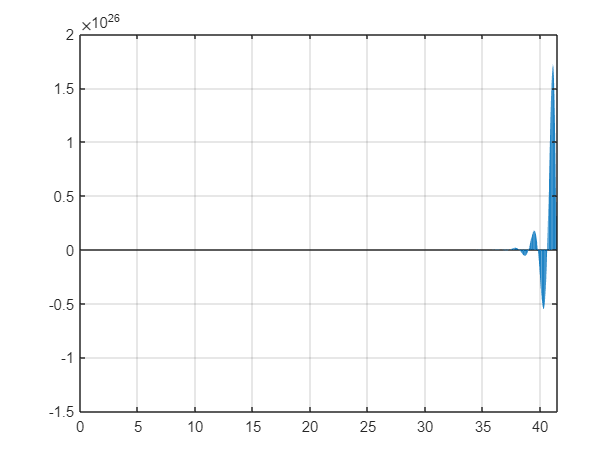




r=t;

et = (r-y)*100;
figure
bar(t,et)
grid

    ERRORE AL GRADINO

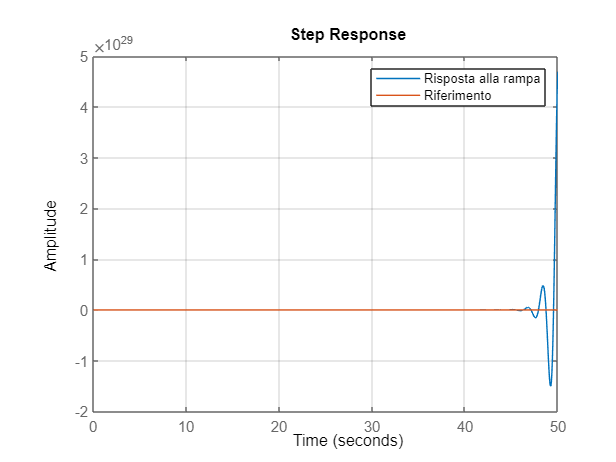


step(Ws/s)
grid
hold on
step(1/s);
hold off
legend("Risposta alla rampa", "Riferimento");

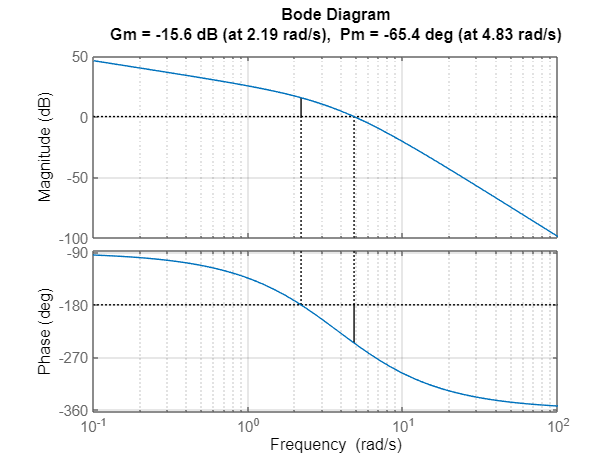


margin(Ls) 
grid




[ampl,phi]=bode(Ls,1.1)

ampl = 16.4524

phi = -138.4330

margine_di_fase=phi+180

margine_di_fase = 41.5670

alfa=1/ampl;


wb=0.8*pi/2

wb = 1.2566


omega_c_primo=1.5;


RETE CORRETTRICE

tau=10/(omega_c_primo*alfa);
C2=(1+s*alfa*tau)/(1+s*tau);
Ls=C2*Ls;
% ora Ls diventa C1*C2*Gs
Ws=feedback(Ls,1)

Ws =
 
                        7470 s + 1120
  ----------------------------------------------------------
  109.7 s^5 + 1251 s^4 + 4763 s^3 + 6062 s^2 + 7525 s + 1120
 
Continuous-time transfer function.



pole(Ws)

ans =   -5.1630 + 1.8488i
  -5.1630 - 1.8488i
  -0.4571 + 1.3420i
  -0.4571 - 1.3420i
  -0.1690 + 0.0000i


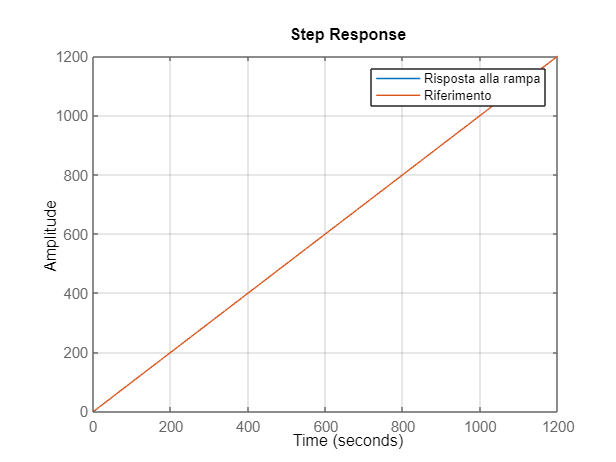

step(Ws/s)
grid
hold on
step(1/s);
hold off
legend("Risposta alla rampa", "Riferimento");


[y,t]=step((1/s)*feedback(Ls,1));

r=t;

et = (r-y)*100;




h = floor(length(t)/2);
max(abs(r(h:end)-y(h:end))./r(h:end))*100

ans = 0.0097

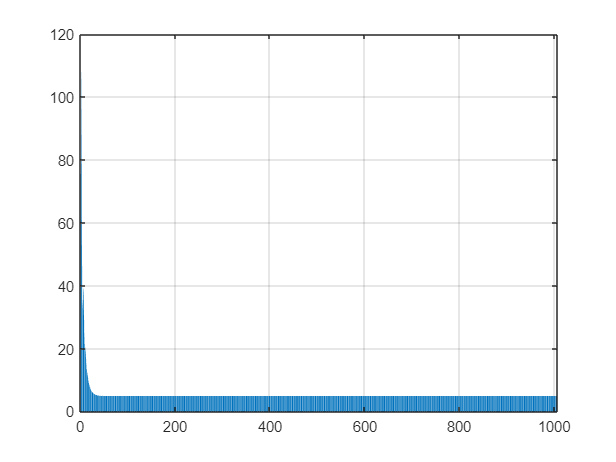


figure
bar(t,et)
grid

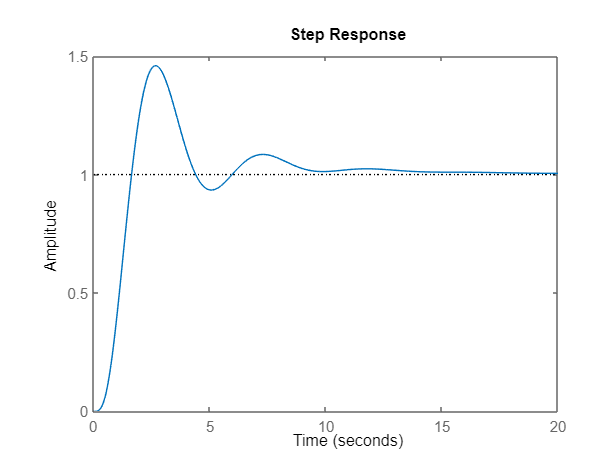





step(Ws)


stepinfo(Ws)

ans = struct with fields:
         RiseTime: 0.9403
    TransientTime: 12.7294
     SettlingTime: 12.7294
      SettlingMin: 0.9055
      SettlingMax: 1.4594
        Overshoot: 45.9426
       Undershoot: 0
             Peak: 1.4594
         PeakTime: 2.6759


Altra rete

S = 0.19;
d = 1/sqrt(1+(pi/log(S))^2)

d = 0.4673

phi_m = 100*d

phi_m = 46.7346

ts = 2;
omega_n  = 3/(d*ts)

omega_n = 3.2096

omega_b = omega_n*sqrt(1-2*d^2+sqrt(4*d^4-4*d^2+2))

omega_b = 4.1982

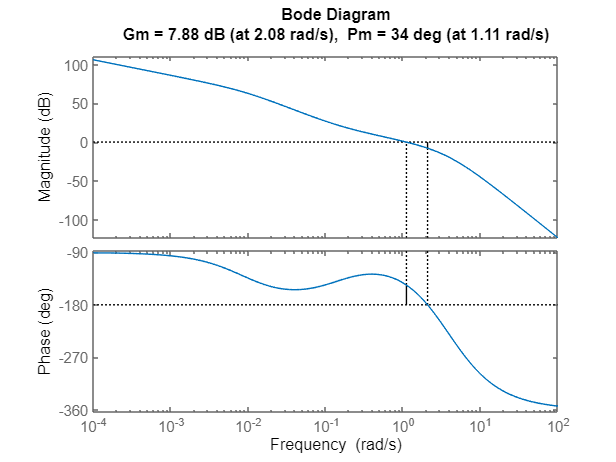


omega_c = 3;

margin(Ls)

[M, phi]=bode(Ls,omega_c)

M = 0.2003

phi = -207.5588

phi_corrente = 180-abs(phi)

phi_corrente = -27.5588

theta=phi_m-phi_corrente

theta = 74.2934

m = 1/M

m = 4.9929

alpha = (m*cos(deg2rad(theta))-1)/(m*(m-cos(deg2rad(theta))))

alpha = 0.0149

T = (1/omega_c)*sqrt((1-m^2)/(alpha^2*m^2-1))

T = 1.6351


Clead = (1+s*T)/(1+s*alpha*T)

Clead =
 
   1.635 s + 1
  -------------
  0.02439 s + 1
 
Continuous-time transfer function.




figure
Ls = Clead*Ls

Ls =
 
                    1.221e04 s^2 + 9302 s + 1120
  ----------------------------------------------------------------
  2.675 s^6 + 140.2 s^5 + 1368 s^4 + 4911 s^3 + 6063 s^2 + 54.87 s
 
Continuous-time transfer function.



margin(Ls)
Fs = feedback(Ls,1)

Fs =
 
                         1.221e04 s^2 + 9302 s + 1120
  --------------------------------------------------------------------------
  2.675 s^6 + 140.2 s^5 + 1368 s^4 + 4911 s^3 + 1.828e04 s^2 + 9357 s + 1120
 
Continuous-time transfer function.



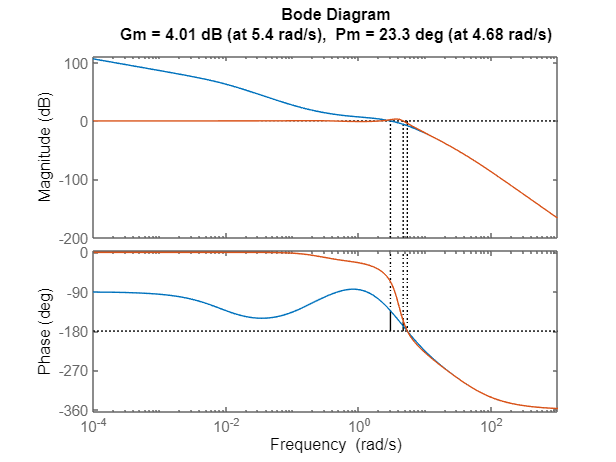



hold on
margin(Fs)

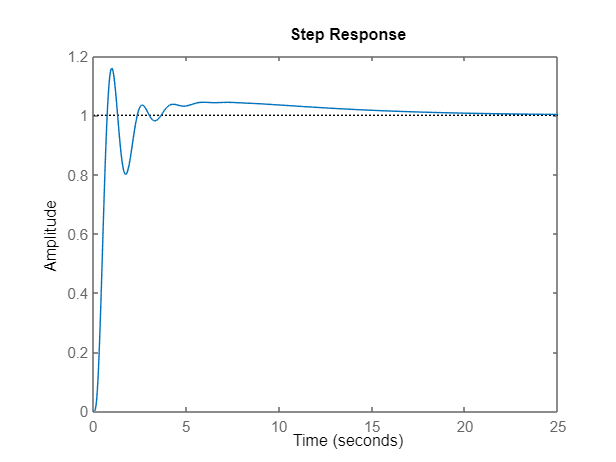

figure
step(Fs)


pole(Fs)

ans =  -40.9185 + 0.0000i
  -8.8682 + 0.0000i
  -1.0275 + 3.9014i
  -1.0275 - 3.9014i
  -0.3932 + 0.0000i
  -0.1804 + 0.0000i


stepinfo(Fs)

ans = struct with fields:
         RiseTime: 0.4354
    TransientTime: 13.9710
     SettlingTime: 13.9710
      SettlingMin: 0.8005
      SettlingMax: 1.1592
        Overshoot: 15.9201
       Undershoot: 0
             Peak: 1.1592
         PeakTime: 0.9867
